clear all, close all, clc

############### ############### ############### ############### 

## Prob-01

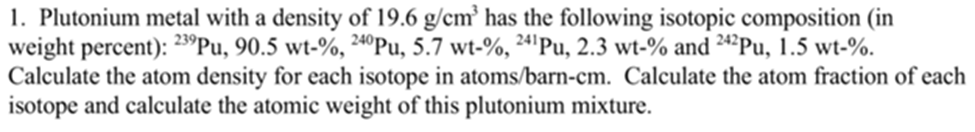

Given,

let, 1 for Pu-239, 2 for Pu-240; 3 for Pu-241; 4 for Pu-242

Na = 6.022e23;      % avogadro's no; #
rh = 19.6;          % density; g/cm^3

A1 = 239.052;       % atomic mass; amu
A2 = 240.053;
A3 = 241.056;
A4 = 242.058;

And,

f_w1 = 0.905;       % weight fraction, Pu-239
f_w2 = 0.057;
f_w3 = 0.023;
f_w4 = 0.015;

We know,

$f_{\mathrm{ai}} =\frac{\frac{f_{\mathrm{wi}} }{A_i }}{\sum_i \;\frac{f_{\mathrm{wi}} }{A_i }}$        $f_{\textrm{ai}} =$ atomic fraction; $f_{\textrm{wi}} =$ weight fraction

the sum-term assumes-

sm = f_w1/A1 + f_w2/A2 + f_w3/A3 + f_w4/A4

sm = 0.0042

So, we have-

f_a1 = f_w1/A1 /sm      % atomic fractin of Pu-239

f_a1 = 0.9056

f_a2 = f_w2/A2 /sm

f_a2 = 0.0568

f_a3 = f_w3/A3 /sm

f_a3 = 0.0228

f_a4 = f_w4/A4 /sm

f_a4 = 0.0148

(Ans)

Now, to calculate the atomic weight of this Pu mixture, we have-


$$A_{\mathrm{Pu}} =\sum_i f_{\mathrm{ai}} A_i$$


That is-

A = A1*f_a1 + A2*f_a2 + A3*f_a3 + A4*f_a4

A = 239.1991

(Ans)

############### ############### ############### ############### 

## Prob-02

Given,

m_n = 1.008665;     % neutron mass; amu
m_p = 1.0072765;    % proton mass; amu 
n_p = 94;           % no. of protons
c = 3e8;            % light velocity; m/s

Now, using the [interactive periodic table](https://ptable.com/?lang=en#Properties), we canf find the following-

m0 = 238.048;       % mass, Pu-238; amu
m1 = 239.052;       % mass, Pu-239
m2 = 240.053;
m3 = 241.057;
m4 = 242.059;       % mass, Pu-242; amu

Now, let's see the following reaction-


$${}^{238}_{94}{Pu}+{}^1_0n\to {}^{239}_{94}{Pu}+Q$$


E = 931.5;          % energy release; MeV

So, binding energies are-

BE_r = (m0 + m_n) *E        % BE of reactants; MeV

BE_r = 2.2268e+05

BE_p = m1 *E                % MeV

BE_p = 2.2268e+05

Q1 = BE_r - BE_p            % MeV

Q1 = 4.3454

(Ans)

Here, the neutron binding energy is equal to Q value of the capture reaction

Then, 


$${}^{239}_{94}{Pu}+{}^1_0n\to {}^{240}_{94}{Pu}+Q$$


BE_r = (m1 + m_n) *E        % BE of reactants; MeV

BE_r = 2.2362e+05

BE_p = m2 *E

BE_p = 2.2361e+05

Q2 = BE_r - BE_p             % MeV

Q2 = 7.1399

(Ans)

Next,


$${}^{240}_{94}{Pu}+{}^1_0n\to {}^{241}_{94}{Pu}+Q$$


BE_r = (m2 + m_n) *E        % BE of reactants; MeV

BE_r = 2.2455e+05

BE_p = m3 *E                % MeV

BE_p = 2.2454e+05

Q3 = BE_r - BE_p             % MeV

Q3 = 4.3454

(Ans)

And, lastly,


$${}^{241}_{94}{Pu}+{}^1_0n\to {}^{242}_{94}{Pu}+Q$$


BE_r = (m3 + m_n) *E        % BE of reactants; MeV

BE_r = 2.2548e+05

BE_p = m4 *E                % MeV

BE_p = 2.2548e+05

Q4 = BE_r - BE_p             % MeV

Q4 = 6.2084

(Ans)

############## ############### ############### ############### 

## Prob-03

We know,

A_h = 1;            
A_o = 16;           % atomic number, oxygen
A_u = 235;
u = 1.66e-27;       % kg/amu

Given, for nuclear radius

$R=1\ldotp 25\times {10}^{-13} \;A^{1/3}$ cm

R_h = 1.25e-13 *A_h^(1/3)   % radius, hydrogen; cm

R_h = 1.2500e-13

R_o = 1.25e-13 *A_o^(1/3)   % ...oxygen; cm

R_o = 3.1498e-13

R_u = 1.25e-13 *A_u^(1/3)   % ...uranium; cm

R_u = 7.7138e-13

(Ans)

**Cross Sectional Area**

Ar_h = pi*R_h^2             % CS area, hydrogen; cm^2

Ar_h = 4.9087e-26

Ar_o = pi*R_o^2             % oxygen; cm^2

Ar_o = 3.1169e-25

Ar_u = pi*R_u^2             % ; cm^2

Ar_u = 1.8693e-24

**Volume**

V_h = 4/3*pi*R_h^3       % ...hydrogen; cm^3

V_h = 8.1812e-39

V_o = 4/3*pi*R_o^3       % ...oxygen; cm^3

V_o = 1.3090e-37

V_u = 4/3*pi*R_u^3       % ...uranium; cm^3

V_u = 1.9226e-36

(Ans)

**Matter Density**

V_h = V_h*1e-6;         % ...; m^3
V_o = V_o*1e-6;         % ...; m^3
V_u = V_u*1e-6;         % ...; m^3

And masses

m_h = A_h*u             % atomic mass, H; kg

m_h = 1.6600e-27

m_o = A_o*u             % ...oxygen; kg

m_o = 2.6560e-26

m_u = A_u*u             % ...uranium; kg 

m_u = 3.9010e-25

So, density becomes

rh_h = m_h /V_h         % density, hydrogen; kg/m^3

rh_h = 2.0290e+17

rh_o = m_o /V_o         % ...oxygen; kg/m^3

rh_o = 2.0290e+17

rh_u = m_u /V_u         % ...uranium; kg/m^3

rh_u = 2.0290e+17

############## ############### ############### ###############

## Prob-04

Let's assume, 1 for U-235 ; 2 for U-238

A_u1 = 235;         % molar mass, u-235; g/mol
A_u2 = 238;         % ...u-238; g/mol
A_o = 16;           % ...oxygen; g/mol

And, we have-

m_u1 = 235.04;      % mass, u-235; amu
m_u2 = 238.05

m_u2 = 238.0500

e = 0.93;           % enrichment, u-235
m_o = 16;           % mass; oxygen; u

So, the mass of the compound would be-

m_uo2 = m_u1*e + m_u2*(1-e) + m_o*2     % mass, UO2; amu

m_uo2 = 267.2507

A_uo2 = m_uo2;                      % molar mass, UO2; g/mol            

Now, let's calculate the weight fractions of the constituents in the compund

f_wu1 = m_u1*e /m_uo2       % weight fraction, u-235; 

f_wu1 = 0.8179

f_wu2 = m_u2*(1-e) /m_uo2

f_wu2 = 0.0624

f_wo = m_o*2 /m_uo2

f_wo = 0.1197

Also, we know the following from the periodic table, mass densities are-

rh_u1 = 19.1;           % density, u-235; g/cm^3
rh_u2 = 19.05;          % ...u-235; g/cm^3
rh_o = 1.429e-3;        % ...oxygen; g/cm^3

Now, let's calculate the atom densities-

rh_uo2 = 10.8;          % density; gm/cm^3
Na = 6.02e23;           % avogadro's number; #/mol

Now, atom densities, $n=f_w \frac{N_a \;\rho }{A}\;$

n_u1 = f_wu1 *Na*rh_uo2 /A_uo2      % atomic density, u-235; #/cm^3

n_u1 = 1.9898e+22

n_u2 = f_wu2 *Na*rh_uo2 /A_uo2      % ...u-238; #/cm^3

n_u2 = 1.5169e+21

n_o =  f_wo  *Na*rh_uo2 /A_uo2      % ...o; #/cm^3

n_o = 2.9129e+21

Now, to change it into different unit

b_cs = 1e24;                % barn/cm^2
n_u1 = n_u1/b_cs            % ...u-235; atoms/barn-cm

n_u1 = 0.0199

n_u2 = n_u2/b_cs            % ...u-238; atoms/barn-cm

n_u2 = 0.0015

n_o =  n_o/b_cs             % ...oxygen; atoms/barn-cm

n_o = 0.0029

(Ans)

############## ############### ############### ############### 

## Prob-05

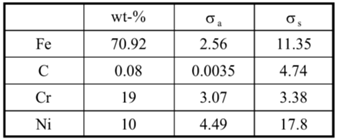

Given,

rh_ss = 7.86;           % density, SS; g/cm^3

fw_fe = 0.7092;         % weight fraction, Fe
fw_c = 0.08e-2;         % ...C
fw_cr = 0.19;           % ...Cr
fw_ni = 0.1;            % ...ni

microscopic Cross sections-

sg_a_fe = 2.56;         % absorption CS, fe; barn
sg_a_c = 0.0035;
sg_a_cr = 3.07;
sg_a_ni = 4.49;

sg_s_fe = 11.35;         % scattering CS, fe; barn
sg_s_c = 4.74;
sg_s_cr = 3.38;
sg_s_ni = 17.8;

Then, we know-

A_fe = 55.845;          % mass, fe; amu
A_c = 12;               % ...C
A_cr = 52;
A_ni = 58.7;

Let's calculate the atomic fraction (redundant)


$$f_{\mathrm{ai}} =\frac{f_{\mathrm{wi}} }{A_i }\;/\sum_i \;\frac{f_{\mathrm{wi}} }{A_i }$$


sm = fw_fe/A_fe + fw_c/A_c + fw_cr/A_cr + fw_ni/A_ni

sm = 0.0181


fa_fe = fw_fe/A_fe /sm

fa_fe = 0.7007

fa_c = fw_c/A_c /sm

fa_c = 0.0037

fa_cr = fw_cr/A_cr /sm

fa_cr = 0.2016

fa_ni = fw_ni/A_ni /sm

fa_ni = 0.0940

So, to calculate the effective atomic weight of the mixture (redundant)

A_ss = A_fe*fa_fe + A_c*fa_c + A_cr*fa_cr + A_ni*fa_ni      % ; amu

A_ss = 55.1769

$n_i =f_{\mathrm{wi}} \;\rho \frac{N_a \;}{A_i }\;$         $f_w =$ weight fraction

b_cs = 1e24;                % ; barn/cm^2

n_fe = fw_fe *Na*rh_ss /A_fe        % atom desnity, fe; #/cm^3

n_fe = 6.0090e+22

n_c =  fw_c  *Na*rh_ss /A_c        % ...c; #/cm^3 

n_c = 3.1545e+20

n_cr = fw_cr *Na*rh_ss /A_cr        % ...cr

n_cr = 1.7289e+22

n_ni = fw_ni *Na*rh_ss /A_ni        % ...ni

n_ni = 8.0609e+21

Now, changing the units-

n_fe = n_fe /b_cs       % ...fe; atoms/b-cm

n_fe = 0.0601

n_c =  n_c  /b_cs       % ...c; atoms/b-cm

n_c = 3.1545e-04

n_cr = n_cr /b_cs       % ...cr; atoms/b-cm

n_cr = 0.0173

n_ni = n_ni /b_cs       % ...ni; atoms/b-cm

n_ni = 0.0081

(Ans)

Let's find the macroscropic absorption CS from the following equation


$$\Sigma_a =n\;\sigma_a$$


Sg_a_fe = sg_a_fe *n_fe         % macroscopic absorption CS, fe; 1/cm

Sg_a_fe = 0.1538

Sg_a_c =  sg_a_c *n_c 

Sg_a_c = 1.1041e-06

Sg_a_cr = sg_a_cr *n_cr 

Sg_a_cr = 0.0531

Sg_a_ni = sg_a_ni *n_ni 

Sg_a_ni = 0.0362


Sg_a_ss = Sg_a_fe + Sg_a_c + Sg_a_cr + Sg_a_ni  % total macro' absorption CS, steel; 1/cm

Sg_a_ss = 0.2431

(Ans)

Similarly, for macroscopic scattering CS,

Sg_s_fe = sg_s_fe *n_fe         % macroscopic scttering CS, fe; 1/cm

Sg_s_fe = 0.6820

Sg_s_c =  sg_s_c *n_c 

Sg_s_c = 0.0015

Sg_s_cr = sg_s_cr *n_cr 

Sg_s_cr = 0.0584

Sg_s_ni = sg_s_ni *n_ni 

Sg_s_ni = 0.1435


Sg_s_ss = Sg_s_fe + Sg_s_c + Sg_s_cr + Sg_s_ni  % total macro' scattering CS, steel; 1/cm

Sg_s_ss = 0.8854

Now, let's find the total CS

Sg_t_fe = Sg_a_fe + Sg_s_fe             % ; 1/cm

Sg_t_fe = 0.8359

Sg_t_c =  Sg_a_c + Sg_s_c

Sg_t_c = 0.0015

Sg_t_cr = Sg_a_cr + Sg_s_cr

Sg_t_cr = 0.1115

Sg_t_ni = Sg_a_ni + Sg_s_ni

Sg_t_ni = 0.1797

And the grand total would be-

Sg_t_ss = Sg_t_fe + Sg_t_c + Sg_t_cr + Sg_t_ni  % total macro' scattering CS, steel; 1/cm

Sg_t_ss = 1.1285

(Ans)

############## ############### ############### ############### 

## Prob-Ex01

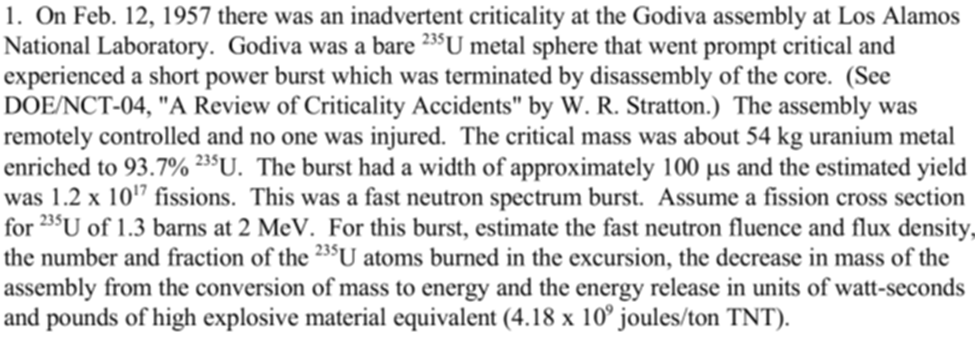

Given,

fs = 1.2e17;        % no. of fissions
t = 1e-4;           % bursting time; s
sg = 1.3*1e-24;     % fission CS; cm^2
m_u = 54e3;         % uranium mass, total; g
A_u = 235.04;       % molar mass, u-235; g/mol
f_wu = 0.937;       % wt fraction/enrichment

So, we have, no. of U-235 in the assembly

$N=f_w m\;\frac{N_a }{A}$        $N=$ number (not, density)

N_u = f_wu *Na*m_u /A_u     % no. of fissile U atoms

N_u = 1.2959e+26

So, the neutron flux would be-


$$\phi =f_s *2\ldotp 5*\frac{1}{t\;\sigma \;}$$


ph = fs*2.5 /(t*sg)     % flux; #/cm^2.s        % 2.5 nu' /fsn

ph = 2.3077e+45

(Ans)

and the fluence

Ph = ph *t          % fluence; #/cm^2

Ph = 2.3077e+41

(Ans)

The faction of atoms destroyed in the burst would be-

fr = fs/N_u         % fraction of U- fissioned

fr = 9.2596e-10

(Ans)

The mass of the fissioned U would be-

m_fs = fr *m_u*f_wu      % U mass- fissioned; g

m_fs = 4.6852e-05

(Ans)

Now, to calculate the release energy, we know, 1 fission releases 207 MeV of energy

E_fs = 207;             % energy/fission; MeV
J_MeV = 1.6e-13;        % J/MeV
J_tonTnT = 4.18e9;      % j/ton-TnT

E = fs *E_fs *J_MeV     % energy released; joules

E = 3974400

E = E /J_tonTnT *2e3    % energy; lb-TnT         

E = 1.9016

(Ans)

############### ############### ############### ############### 

## Prob-Ex02

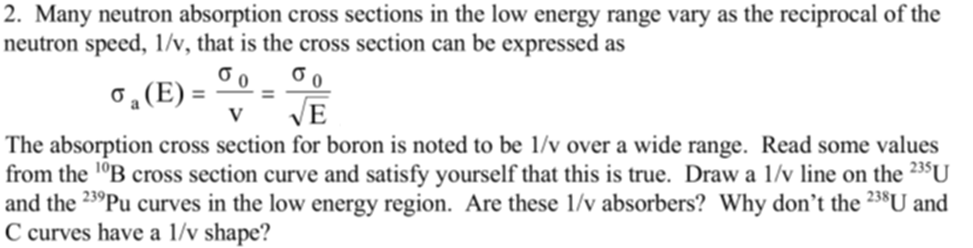

**for Boron-10**

The given relationship


$$\sigma_a =\frac{\sigma_0 }{\sqrt{\;E}}$$


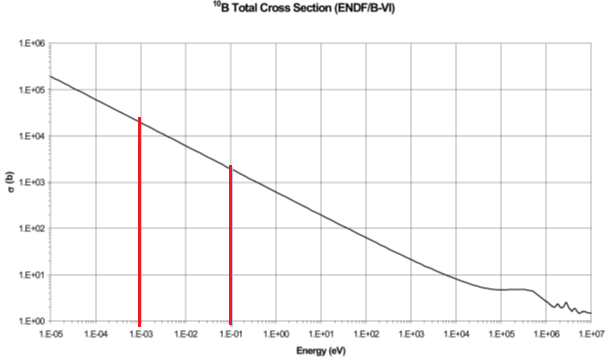

From the above figure, we see, for total CS of B-10, in log-log plotting, the cross section proportional to 1/v is a straight line with a slope of -0.5. It is seen that, the CS of B-10 is almost 1.5e+04 barns at 1e-03 eV, and 1.5e+03 barns at 1e-01 eV. So, it shows a 1/v relationship.

**for U-235, and Pu-239**

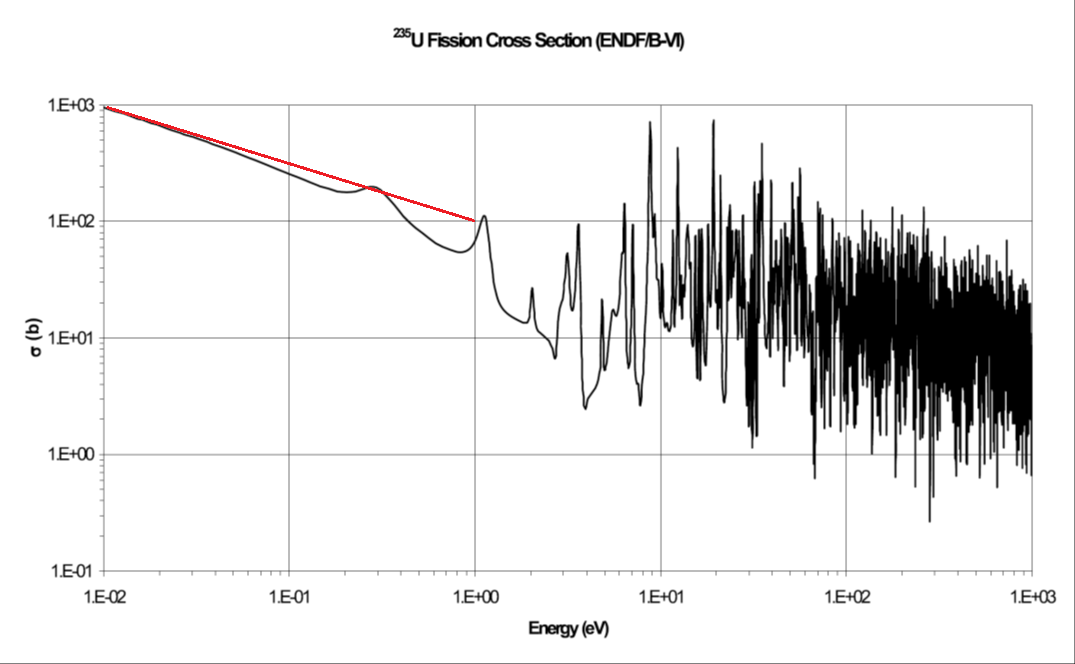 

The U-235 fissin CS is ~ 1e+03 barns at 1e-02 eV and and below 1e+02 at 1e-01 eV. Also, there's a resonance structure in the low energy range. The red line here shows the 1/v line in the low eV region.

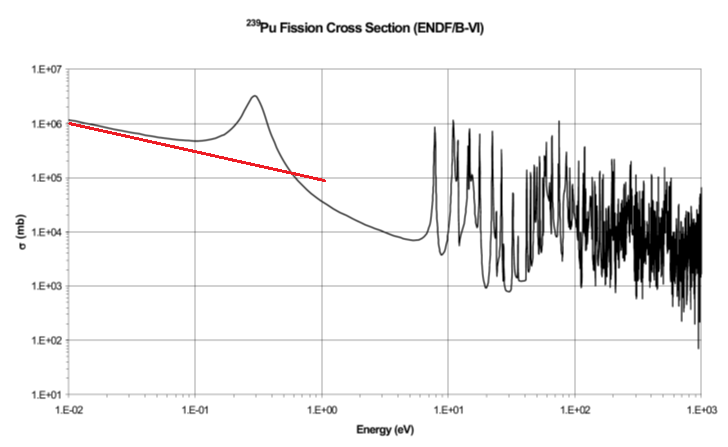

Similarly, for Pu-239 fission CS has large resonance at about 3 eV. The 1/v line is shown in red for Pu-239 at lower energy region.

So, we can say that U-235 and Pu-239 are almost a 1/v absorber. 

**for U-238**

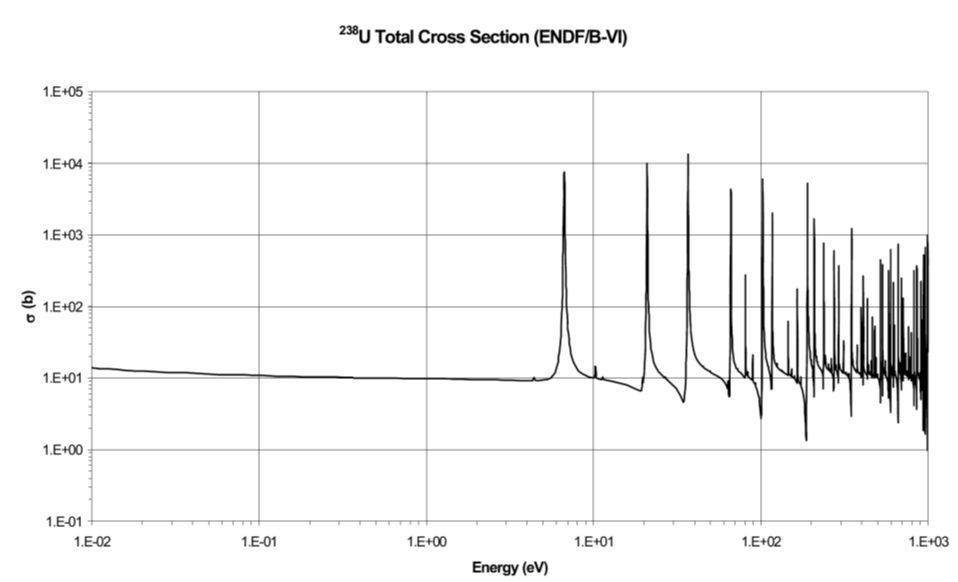

The U-238 and C curve doesn't show 1/v behavior because the plots shows the total cross saection are dominated by scattering, not absorption. Scattering CS are generally constant with energy-change. 